%==============Load sound file=======================
load splat;
y = y(1:8192);
sound(y);


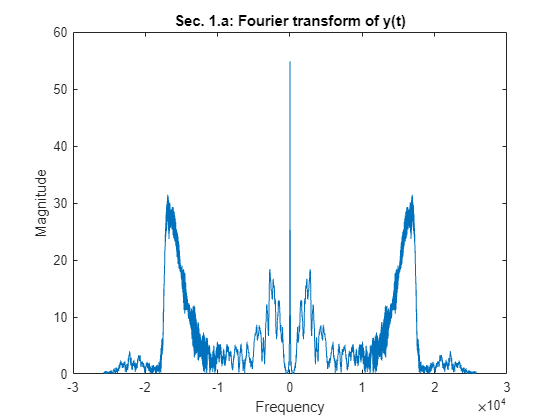

%% ============Fourier Transform ===================
Y = fftshift(fft(y));
N = 8192;
fs = 8192;
W = [-pi:2*pi/N:pi-pi/N]*fs;

figure;
subplot(1,1,1);
plot(W,abs(Y));
xlabel("Frequency");ylabel("Magnitude");title("Sec. 1.a: Fourier transform of y(t)");

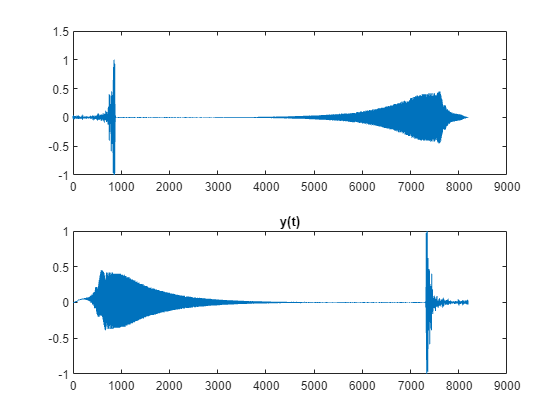

%%==============1-b : Conj(Y)======================
Y1 = conj(Y);
y1 = real(ifft(Y1));
sound(y1)
figure;
subplot(2,1,1);
title('y1(t)');
plot(y1);
subplot(2,1,2);
plot(y);
title('y(t)');

%%================1-c : y2====================
Y2 = abs(Y);
y2 = real(ifft(Y2));
sound(y2,fs);

%%==================1-e:y3====================
Y3 = Y./Y2;
y3 = real(ifft(Y3));
sound(y3,fs);

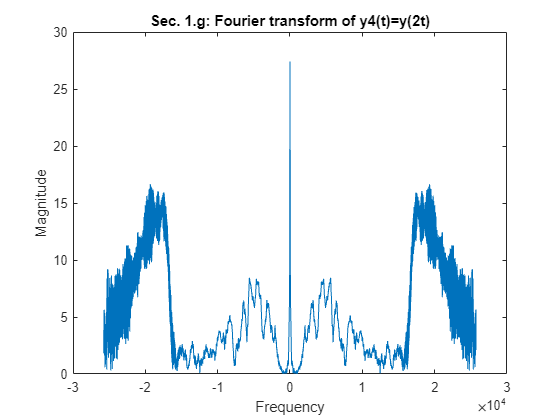

%%===================1-g: Compression in time=====================
fs=8192;
n = 1:2:8192;
y4 = y(n);
sound(y4,fs);
Y4 = fftshift(fft(y4,fs));
figure;
subplot(1,1,1);
plot(W,abs(Y4));
xlabel("Frequency");ylabel("Magnitude");title("Sec. 1.g: Fourier transform of y4(t)=y(2t)");

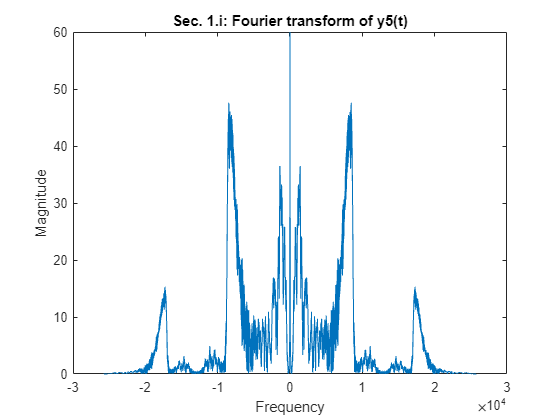

%%===================1-i: Expansion in time========================
x = zeros(2.*fs,1);
n = 1:1:fs;
x(2.*n) = y(n);
h = [1 2 1]./2;
y5 = filter(h, 1, x);
Y5 = fftshift(fft(y5));
N = 2.*8192;
fs = 8192;
W_5 = (-pi:2*pi/N:pi-pi/N).*fs;
figure;
subplot(1,1,1);
plot(W_5,abs(Y5));
xlabel("Frequency");ylabel("Magnitude");title("Sec. 1.i: Fourier transform of y5(t)");ylim([0 60]);

# Modulation

## A)

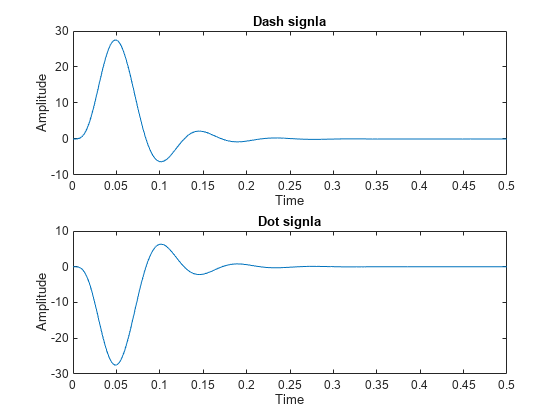

z = [dash dash dot dot];

%plot dash and dot
figure;
subplot(2,1,1);
plot(t(1:2000) , dash); xlabel("Time");ylabel("Amplitude");title("Dash signla");
subplot(2,1,2);
plot(t(1:2000) , dot); xlabel("Time");ylabel("Amplitude");title("Dot signla");


%Plot z:
figure;
subplot(1,1,1);
plot(t , z); xlabel("Time");ylabel("Amplitude");title("z(t) signla");

## B)

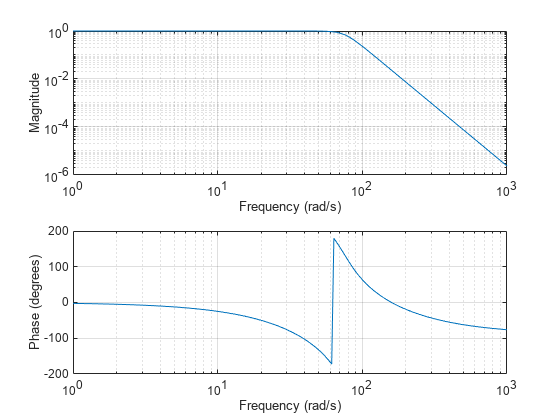

freqs(bf,af);

## C)

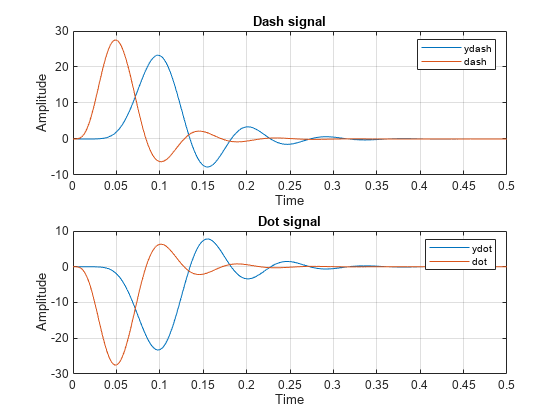

ydash = lsim(bf,af, dash, t(1:length(dash)));
ydot = lsim(bf, af, dot, t(1:length(dot)));

%plot dash:
figure;
subplot(2,1,1);
plot(t(1:2000) , ydash);
grid on;
hold on;
plot(t(1:2000) , dash);
xlabel("Time");ylabel("Amplitude");title("Dash signal");
legend("ydash","dash");
subplot(2,1,2);
plot(t(1:2000) , ydot);
grid on;
hold on;
plot(t(1:2000) , dot);
xlabel("Time");ylabel("Amplitude");title("Dot signal");
legend("ydot","dot");

## D)

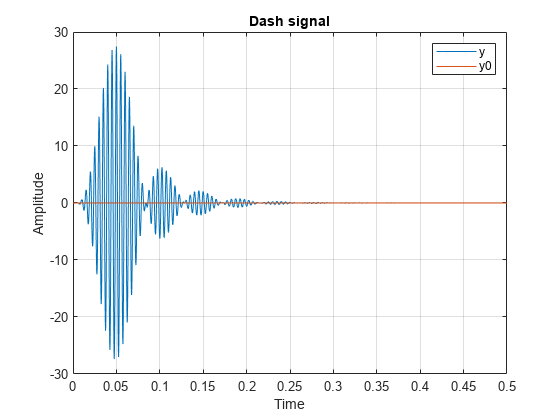

y = dash.*cos(2*pi*f1.*t(1:length(dash)));
yo = lsim(bf,af,y,t(1:length(dash)));
figure;
subplot(1,1,1);
plot(t(1:2000) , y);
grid on;
hold on;
plot(t(1:2000) , yo);
xlabel("Time");ylabel("Amplitude");title("Dash signal");
legend("y","y0");
hold off;

## f)

m1 = 2.*lsim(bf,af,x.*cos(2*pi*f1.*t(1:length(x))),t(1:length(x)));

## G)

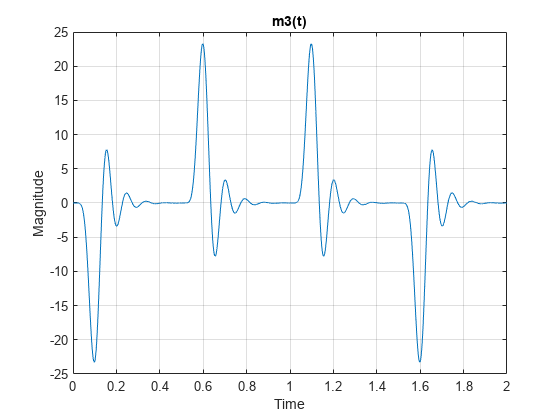

m3 = 2.*lsim(bf,af,x.*sin(2*pi*f1.*t(1:length(x))),t(1:length(xo)));
figure;
subplot(1,1,1);
plot(t,m3);xlabel("Time");ylabel("Magnitude");title("m3(t)");grid("on");

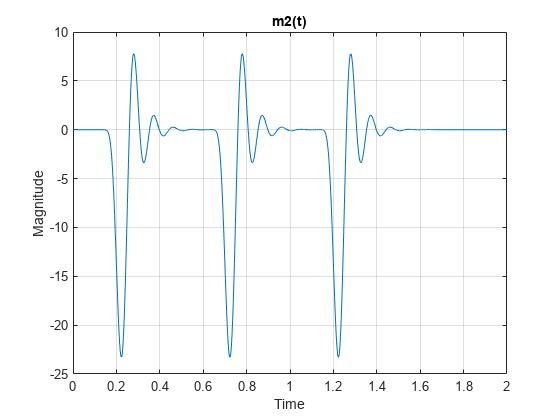



m2 = 2.*lsim(bf,af,x.*sin(2*pi*f2.*t(1:length(x))),t(1:length(xo)));
figure;
subplot(1,1,1);
plot(t,m2);xlabel("Time");ylabel("Magnitude");title("m2(t)");grid("on");

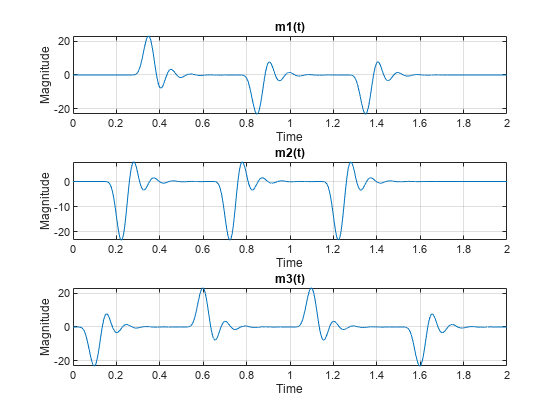




figure;
subplot(3,1,1);
plot(t,m1);xlabel("Time");ylabel("Magnitude");title("m1(t)");grid("on");
subplot(3,1,2);
plot(t,m2);xlabel("Time");ylabel("Magnitude");title("m2(t)");grid("on");
subplot(3,1,3);
plot(t,m3);xlabel("Time");ylabel("Magnitude");title("m3(t)");grid("on");